## Gauntlet Challenge - QEA2

Plotting potential field 

clc; clear; clf; 

% Create a meshgrid
[x,y] = meshgrid(-2:0.05:2,-2:0.05:2);

% Establishing weights for each of the obstacles, the BoB, and obstructions 
Bob_weight = 26.95; 
Box_1 = 11.28;
Box_2 = 1.5; 
Box_3 = .5;
Circle_box = 2.4;
indent = 6; 
dot = 0.09; 

% Defining equation for the four obstacles, two obstructions, and the Bob
v = Bob_weight*(log(sqrt((x+1.031).^2 + (y-.562).^2))) - Box_1*(log(sqrt((x+0.44).^2 + (y-.574).^2))) - Box_2*(log(sqrt((x-.28).^2 + (y-.355).^2))) - Circle_box*(log(sqrt((x+.337).^2 + (y+.381).^2))) - Box_3*(log(sqrt((x-.491).^2 + (y+.494).^2))) - indent*(log(sqrt((x+1.0475).^2 + (y+.914).^2))) - dot*(log(sqrt((x).^2 + (y-.572).^2))); 

% Plotting potential field
contourf(x, y, v, 'k', 'ShowText', 'On'); %hold on; 

%Establish weights for the walls
johny1 = 0.95; 
johny2 = 0.29; 
johnx1 = 0.33;
johnx2 = 0.95; 

% Loop through source points from -1.2 to +1.2 for x-axis
for a = -1.2:0.1:1.2
    v = v - johny1*log(sqrt((x-a).^2 + (y-1).^2));
    v = v - johny2*log(sqrt((x-a).^2 + (y+1.2).^2));
end

% Loop through source points from -1.2 to +1 for y-axis
for b = -1.2:0.1:1
    v = v - johnx1*log(sqrt((x+1.2).^2 + (y-b).^2));
    v = v - johnx2*log(sqrt((x-1.2).^2 + (y-b).^2));
end

Plotting Quiver plot


clf;

% Create a meshgrid
[x,y]=meshgrid(-2:0.009:2,-2:0.009:2);

% Add sources (obstacles and BoB)
fx = ((x+1.031)./((x+1.031).^2+(y-0.562).^2)) - ((x+0.44)./((x+0.44).^2+(y-.574).^2)) - ((x-0.28)./((x-0.28).^2+(y-0.355).^2)) - ((x+0.337)./((x+0.337).^2+(y+0.381).^2)) - ((x-0.491)./((x-0.491).^2+(y+0.494).^2));
fy = ((y-0.562)./((x+1.031).^2+(y-0.562).^2)) - ((y-0.574)./((x+0.44).^2+(y-0.574).^2)) - ((y-0.355)./((x-.28).^2+(y-0.355).^2)) - ((y+0.381)./((x+.337).^2+(y+0.381).^2)) - ((y+0.494)./((x-0.491).^2+(y+0.494).^2));

% Add walls 
for a = -3:0.3:3
    fx = fx - ((x-a)./((x-a).^2 + (y-1).^2));
    fy = fy - ((y-1)./((x-a).^2 + (y-1).^2));

    fx = fx - ((x-a)./((x-a).^2 + (y+1.2).^2));
    fy = fy - ((y+1.2)./((x-a).^2 + (y+1.2).^2));
end

for b = -3:0.3:2
    fx = fx - ((x+1.2)./((x+1.2).^2 + (y-b).^2));
    fy = fy - ((y-b)./((x+1.2).^2 + (y-b).^2));
 
    fx = fx - ((x-1.2)./((x-1.2).^2 + (y-b).^2));
    fy = fy - ((y-b)./((x-1.2).^2 + (y-b).^2));
end

% Plot Quiver plot 
quiver(x,y,fx,fy,30); hold on; 
title("Gauntlet Quiver Plot");
xlabel("X Position (Meters)");
ylabel("Y Position (Meters)");


Plotting predicted path and running the Neato/ Neato simulation 

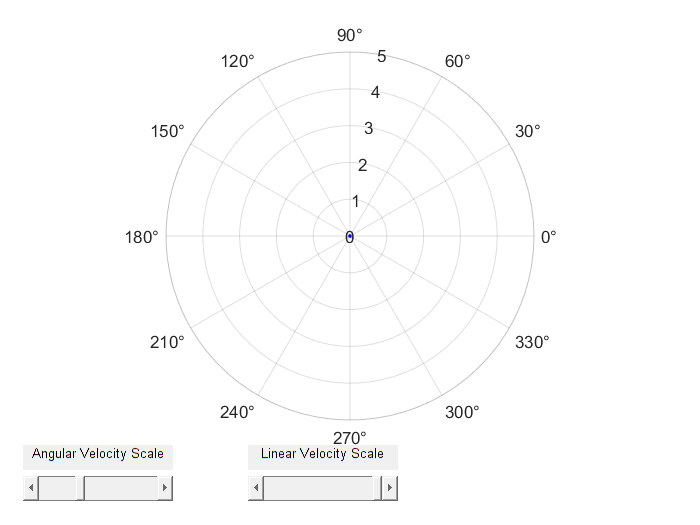

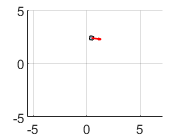

clf; 

% Get expected positions of Neato
final = [];

% Defining wheel base and step sizes
wheelBase = 0.235;          
lambda = 0.1; 

syms x y f;

% Equation for contour  
f = Bob_weight*(log(sqrt((x+1.031).^2 + (y-.562).^2))) - Box_1*(log(sqrt((x+0.44).^2 + (y-.574).^2))) - Box_2*(log(sqrt((x-.28).^2 + (y-.355).^2))) - Circle_box*(log(sqrt((x+.337).^2 + (y+.381).^2))) - Box_3*(log(sqrt((x-.491).^2 + (y+.494).^2))) - indent*(log(sqrt((x+1.0475).^2 + (y+.914).^2))) - dot*(log(sqrt((x).^2 + (y-.572).^2))); 

% Loop through source points from -1.2 to +1.2 for x-axis
for a = -1.2:0.1:1.2
 f = f - johny1*log(sqrt((x-a).^2 + (y-1).^2));
 f = f - johny2*log(sqrt((x-a).^2 + (y+1.2).^2));
end

% Loop through source points from -1.2 to +1 for y-axis
for b = -1.2:0.1:1
    f = f - johnx1*log(sqrt((x+1.2).^2 + (y-b).^2));
    f = f - johnx2*log(sqrt((x-1.2).^2 + (y-b).^2));
end

% Connect to Neato/ Neato simulation 
[sensors,vels] = neatoSim(0.933, 0.838, 0); 
[sensors,vels]=neato('192.168.16.87');  
 
vels.lrWheelVelocitiesInMetersPerSecond=[0,0];
pause(1);

% Find gradient of contour
grad = gradient(f, [x, y]);

% Initialize position
position_new = [0.933; 0.838];
head = [0;1]; 

% Establishing speed parameters 
linear_speed = 0.3; 
angular_speed = 0.1*2/wheelBase;

% Determining the gradient value at the starting position
gradValue = -1*double(subs(grad, {x, y}, {position_new(1), position_new(2)}));

% Gather 30 points
counter = 30; 

while counter > 0 

    % Calculate angle of turn for the Neato  
    head_angle = atan2(head(2,:), head(1,:));
    gradient_angle = atan2(gradValue(2,:), gradValue(1,:)); 
    total_angle = gradient_angle - head_angle; 
        if total_angle > pi 
            total_angle = total_angle - 2*pi; 
        end
     direction = sign(total_angle); % Determining direction of turn (counterclockwise or clockwise)

    % Using time as a constraint for the turn 
    angle_time = abs(total_angle) / angular_speed; 

    % Tic/toc function to execute turn 
    t_0 = clock; 
   
        while (etime(clock, t_0) < angle_time) 
            vels.lrWheelVelocitiesInMetersPerSecond = [-direction*angular_speed*wheelBase/2, direction*angular_speed*wheelBase/2];
            pause(0.01); 
        end 

    vels.lrWheelVelocitiesInMetersPerSecond = [0,0]; % Stopping wheels
    pause(.1);
    head = gradValue; % Updating the position Neato is facing

    % Calculating distance before next turn  
    distance = lambda;
    distance_time = distance / linear_speed; 
    
    % Tic/toc function to execute forward distance
    t_1 = clock;  
    
        while (etime(clock, t_1) < distance_time)
            vels.lrWheelVelocitiesInMetersPerSecond = [linear_speed, linear_speed];
            pause(0.01); 
        end 

    vels.lrWheelVelocitiesInMetersPerSecond = [0,0]; %stopping wheels
    pause(.1);

    
    % Updating and storing new position for next iteration  
    position_new = position_new + (lambda * gradValue) ./ norm(gradValue);  
    final = [final position_new];
    
    % Determinig gradient for current position
    gradValue = -1*double(subs(grad, {x, y}, {position_new(1), position_new(2)}));
    
    % Update counter
    counter = counter - 1;
end


% Building a meshgrid
[x,y] = meshgrid(-2:0.05:2,-2:0.05:2);

% Ploting contour map and theoretical/predicted path to the BoB 
contourf(x, y, v, 30, 'ShowText', 'On'); hold on; 
plot(final(1, :), final(2, :), 'r', 'LineWidth', 2.5)
title("Gauntlet Gradient Descent on Contour")
legend("Contour", "Expected Path")
xlabel("X Position (Meters)")
ylabel("Y Position (Meters)")


Using encoder data to plot the theoretical versus measured path and calculating total distance traveled and time taken 

% Storing encoder data in variables 
% column 1 - time, column 2 - left wheel, column 3 - right wheel
encoder_data = encoder_data(1:30,:); 
encoder_time = encoder_data(:,1); 

Unrecognized function or variable 'encoder_data'.

encoder_leftwheel = encoder_data(:,2);
encoder_rightwheel = encoder_data(:,3);

% Calculate wheel velocities
left_vel = diff(encoder_leftwheel) ./ diff(encoder_time);
right_vel = diff(encoder_rightwheel) ./ diff(encoder_time);
left_vel(size(left_vel)+1) = 0;
right_vel(size(right_vel)+1) = 0;

encoder_vel = (left_vel + right_vel) ./ 2;
encoder_omega = (right_vel - left_vel) ./ wheelBase;

% Establishing starting position and initial heading 
position_compare = [0.933; 0.838];
heading = [1; 0];
diff_encoder_time = diff(encoder_time);

for i = 1:length(diff_encoder_time)
    position_compare(:,i+1) = position_compare(:,i) + (heading(:,i) .* encoder_vel(i) .* diff_encoder_time(i));
    
    % Rotate heading
    theta = encoder_omega(i) * diff_encoder_time(i);
    rotate = [cos(theta), -sin(theta); sin(theta), cos(theta)];
    heading(:, i+1) = rotate * heading(:,i);
end

% Building a meshgrid
[x,y] = meshgrid(-2:0.05:2,-2:0.05:2);

% Graphing contours
contourf(x, y, v, 'k', 'ShowText', 'On');

% Plotting expected versus observed positions
plot(position_compare(1,:), position_compare(2,:), 'b', 'LineWidth', 1.5)
plot(final(1, :), final(2, :), 'r', 'LineWidth', 2.5) 
title('Expected vs Observed Path'); 
legend("Contours", "Expected Path", "Observed Path")
xlabel("X Position (Meters)")
ylabel("Y Position (Meters)")

% Compute total distance travelled and time taken by the Neato  
x_change = diff(position_compare(1,:));
y_change = diff(position_compare(2,:));
sums = sqrt(x_change.^2 + y_change.^2);
distance_traveled = sum(sums)
